Ejemplo Jacobiano Simbólico

syms x1 x2
xs = [x1;x2];
f1 = xs(1)^2 + xs(1)*xs(2) - 10;
f2 = xs(2) + 3*xs(1)*xs(2)^2 - 57;
fs = [f1; f2]

$$fs = \left(\begin{array}{c} {x_{1}}^{2}+x_{2}\,x_{1}-10\\ 3\,x_{1}\,{x_{2}}^{2}+x_{2}-57 \end{array}\right)$$

Js = jacobian(fs,xs)

$$Js = \left(\begin{array}{cc} 2\,x_{1}+x_{2} & x_{1}\\ 3\,{x_{2}}^{2} & 6\,x_{1}\,x_{2}+1 \end{array}\right)$$


syms x1 x2 x3
xs = [x1;x2;x3];
fs = [ 3*xs(1) - cos(xs(2)*xs(3)) - 3/2  ;
  4*xs(1)^2 - 625*xs(2)^2 + 2*xs(2) - 1  ;
   exp(-xs(1)*xs(2)) + 20*xs(3) + (10*pi-3)/3]

$$fs = \left(\begin{array}{c} 3\,x_{1}-\cos\left(x_{2}\,x_{3}\right)-\frac{3}{2}\\ 4\,{x_{1}}^{2}-625\,{x_{2}}^{2}+2\,x_{2}-1\\ 20\,x_{3}+{\mathrm{e}}^{-x_{1}\,x_{2}}+\frac{5332248173269055}{562949953421312} \end{array}\right)$$

Js = jacobian(fs,xs)

$$Js = \left(\begin{array}{ccc} 3 & x_{3}\,\sin\left(x_{2}\,x_{3}\right) & x_{2}\,\sin\left(x_{2}\,x_{3}\right)\\ 8\,x_{1} & 2-1250\,x_{2} & 0\\ -x_{2}\,{\mathrm{e}}^{-x_{1}\,x_{2}} & -x_{1}\,{\mathrm{e}}^{-x_{1}\,x_{2}} & 20 \end{array}\right)$$

Acodeón Segundo Parcial ANPC

- Dems. de Gauss-Seidel

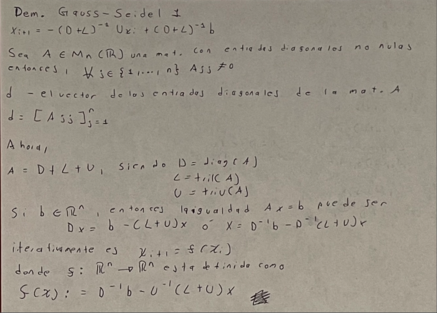

        2. Dems. de Gauss-Seidel

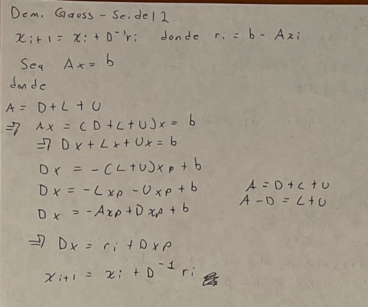

Gauss-Seidel Elegante

function [x,i] = gaussSeidelEleg(A,b)
    if ~isDiagDom(A)
        warning('La matriz no es diagonalmente dominante')
    end
    tol=eps;
    MAXi=1000;
    i=0;
    x=zeros(size(b));
    D=diag(diag(A));
    L=tril(A,-1);
    M=D+L;
      
    do=true;
    while do 
        xp=x;
        r=b-A*x;
        x=x+M\r;
        i=i+1;
        do=norm((x-xp)./x,Inf)>tol && i<MAXi;  
    end    
end

Es Diagonal Dominante

function res= isDiagDom(A)
   res=true;
   [m,n]=size(A);
   if m~=n, error('La matriz no es cuadrada'), end
   
   i=1;
   while res && i<n
       res=abs(A(i,i))>sum(abs(A(i,[1:i-1 i+1:n])));
       i=i+1;
   end
end

Descenso Max

function [x, i] = DescensoMaximoEleg(A, b, x)
    if ~PD(A)
        error('La matriz A no es positiva definida.');
    end
    
    max_iter = 52*10; % max_iter = 444;
    tol = eps();
    r = b - A * x;
    i = 0;
    cond = norm(r) ~= 0;
    while cond
        xp = x;
        alpha = dot(r, r) / (r' * A * r);  
        x = x + alpha * r;
        r = b - A * x;
        i = i + 1;
        cond = norm(r) ~= 0 && norm((x - xp) / x, inf) > tol && i < max_iter;
    end
end

Positiva Definida en 1 línea de cod (Crit. Sylvester)

function res = PD(A)
    [m, n] = size(A);
    res = m == n && all(eig(A) > 0) && issymmetric(A);
end

Gradiente Conjugado

function [x, i] = GradienteConjugadoEleg(A, b, x)
    if ~PD(A)
        error('La matriz A no es positiva definida.');
    end
    
    max_iter = length(x);
    tol = eps();
    
    r = b - A * x;
    d = r;
    
    i = 0;
    cond = norm(r) ~= 0;
    while cond
        xp = x;
        rr = dot(r, r);
        alpha = rr / (d' * A * d);
        
        x = x + alpha * d;
        r = b - A * x;
        d = r + (dot(r, r) / rr) * d;
        
        i = i + 1;
        cond = norm(r) ~= 0 && norm((x - xp) / x, inf) > tol && i < max_iter;
    end
end

Newton-Raphson Varias Variable

function [x,i] = NewtonRaphsonVVEleg(f,J,x)
    i=0;
    MAX=80;
    TOL=eps();
    fx=f(x);
    do = true;
    
    while do
        xp=x;
        x=xp-J(xp)\fx;
        fx=f(x);
        i=i+1;
        do = i<MAX  && any(fx) && norm((x-xp)./x,inf)>TOL;
    end
end

Jacobiana simbólico

function y=jacobiano(f,x)
    fs=sym(f);
    n=length(fs);
    y=zeros(n,n);
end

Gradiente

function [x,dx0,dy0,i] = gradiente(f,dx,dy,x,eps)
    syms t; 
    do=true;
    i=0;
    while do
        i=i+1
        dx0=dx(x(1),x(2)); %(x,-) en dx
        dy0=dy(x(1),x(2)); %(-,y) en dy
        x0=x+[dx0,dy0]*t; 
        
        ft=f(x0(1),x0(2));
        tsym= sym(ft);
        dts=diff(tsym);
        dt = matlabFunction(dts);
        tE=solve(dt,t);
        x=x+tE*[dx0,dy0]
        
        
        do=abs(dx0)>eps||abs(dy0)>eps;
    end
end

Criterio Silvester

function res = SylvesterCrit(A)
res= true;
[tam1,tam2]=size(A);
if tam1==tam2    
   i=1;
    while(res && i<= tam1)
        if det(A(i,i))<=0
        res=false;
        end
    i=i+1;
    end 
end
end